x1= readtable("C:\Users\HP\Desktop\After lockdown\India\India1.csv" )

x1 = 207×9 table
       date       total_cases    new_cases    total_deaths    new_deaths    new_tests    total_tests    Tests_per_million    Cases_per_million
    __________    ___________    _________    ____________    __________    _________    ___________    _________________    _________________

    12/31/2019         0             0             0              0             0             0                 0                    0        
    01/01/2020         0             0             0              0             0             0                 0                    0        
    01/02/2020         0             0             0              0             0             0         

x2=readtable("C:\Users\HP\Desktop\After lockdown\India\covid-tests-cases-deaths-per-million.csv" )

x2 = 207×4 table
       Date       CumulativeTestsPerMillion    ConfirmedCasesPerMillion_casesPerMillion_    ConfirmedDeathsPerMillion_deathsPerMillion_
    __________    _________________________    _________________________________________    ___________________________________________

    12/31/0019                0                                    0                                             0                     
    01/01/0020                0                                    0                                             0                     
    01/02/0020                0                                    0                                             0                     
    01/03/0020                0                                    0                                             0                     
    01/04/0020                

x3=readtable("C:\Users\HP\Desktop\After lockdown\India\covid-stringency-index.csv")

x3 = 206×2 table
       Date       Stringency_Index
    __________    ________________

    01/01/0020           0        
    01/02/0020           0        
    01/03/0020           0        
    01/04/0020           0        
    01/05/0020           0        
    01/06/0020           0        
    01/07/0020           0        
    01/08/0020           0        
    01/09/0020           0        
    01/10/0020           0        
    01/11/0020           0        
    01/12/0020           0        
    01/13/0020           0        
    01/14/0020           0        
    01/15/0020           0        
    01/16/0020           0        


x4=readtable("C:\Users\HP\Desktop\After lockdown\India\case-fatality-rate-vs-tests-per-confirmed-case.csv")

x4 = 176×3 table
       Date       CaseFatalityRate___    TestsPerConfirmedCase
    __________    ___________________    _____________________

    01/30/0020             0                      NaN         
    01/31/0020             0                      NaN         
    02/01/0020             0                      NaN         
    02/02/0020             0                      NaN         
    02/03/0020             0                      NaN         
    02/04/0020             0                      NaN         
    02/05/0020             0                      NaN         
    02/06/0020             0                      NaN         
    02/07/0020             0                      NaN         
    02/08/0020             0                      NaN         
    02/09/0020             0                      NaN         
    02/10/0020             0                      NaN        

x5=readtable("C:\Users\HP\Desktop\After lockdown\India\changes-visitors-covid.csv")

x5 = 158×7 table
       Date       Retail_Recreation___    Grocery_PharmacyStores___    Residential___    TransitStations___    Parks___    Workplaces___
    __________    ____________________    _________________________    ______________    __________________    ________    _____________

    02/16/0020              1                         2                       0                   3                3              5     
    02/17/0020              2                         2                       0                   2                3              0     
    02/18/0020             -1                         1                       0                   1                3              4     
    02/19/0020              0                         2    

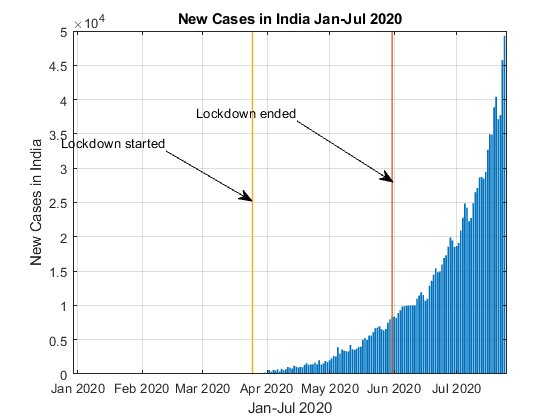

%Jan-Jul 2020 New Cases in India
bar(x1.date,x1.new_cases)

hold on

t2mark=datetime(2020,05,31);
plot([t2mark t2mark], ylim,"LineWidth",1);
t3mark=datetime(2020,03,25);
plot([t3mark t3mark], ylim,"LineWidth",1);
grid on
title("New Cases in India Jan-Jul 2020")
xlabel("Jan-Jul 2020")
ylabel("New Cases in India")

annotation('textarrow',[0.5304 0.7018],[0.7119 0.5667],'String','Lockdown ended')
annotation('textarrow',[0.2964 0.45],[0.6405 0.5214],'String','Lockdown started')
hold off

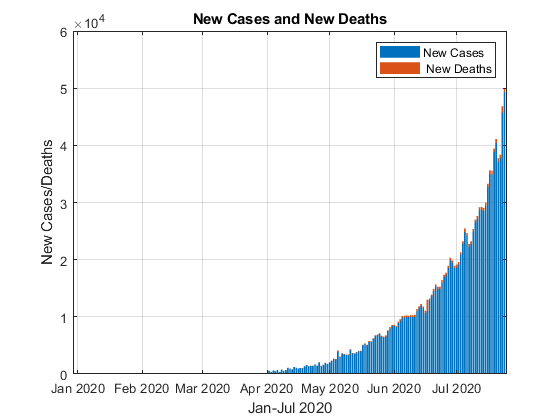

% Total cases , new cases, deaths
a=[x1.date];
c=[x1.new_cases,x1.new_deaths];
bar(a,c,'stacked')
legend("New Cases"," New Deaths")
title("New Cases and New Deaths")
xlabel("Jan-Jul 2020")
ylabel("New Cases/Deaths")
grid on

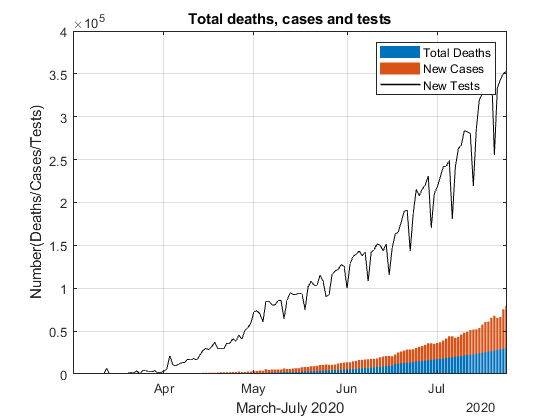



d=[x1.total_deaths,x1.new_cases];
bar(a,d,'stacked')

hold on
plot(a,x1.new_tests,"LineWidth",1,"Color",[0 0 0])

grid on
hold off


xlim([datetime(2020,3,1,19,11,60)...
      datetime(2020,7,24,4,47,60)])    

 legend({'Total Deaths','New Cases','New Tests'})
 title("Total deaths, cases and tests")
 xlabel("March-July 2020")
 ylabel("Number(Deaths/Cases/Tests)")

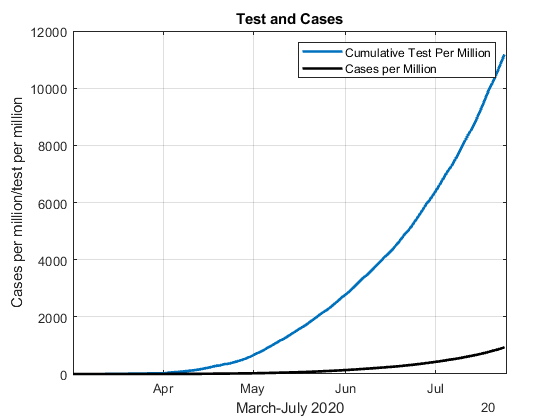



plot(x2.Date,x2.CumulativeTestsPerMillion,"LineWidth",2)
hold on
plot(x2.Date,x2.ConfirmedCasesPerMillion_casesPerMillion_,"LineWidth",2,"Color",[0 0 0])
legend("Cumulative Test Per Million", "Cases per Million")  
grid on
hold off

xlim([datetime(20,3,1,20,27,39)...
      datetime(20,7,24,20,27,39)])
xlabel("March-July 2020")
ylabel("Cases per million/test per million")
title("Test and Cases")

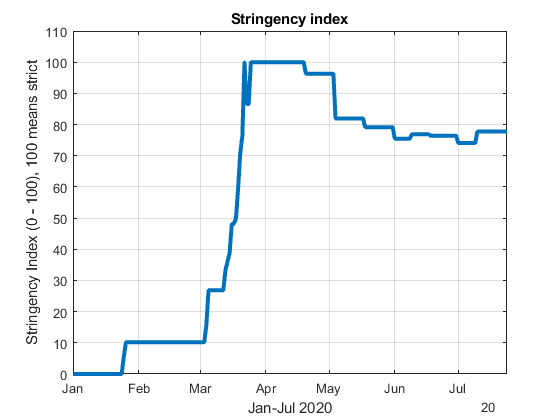

plot(x3.Date,x3.Stringency_Index,"LineWidth",3)
hold on

title("Stringency index")

xlim([datetime(20,1,1,0,0,0)...
      datetime(20,7,24,0,0,0)])
ylim([0.0 110.0])
xlabel("Jan-Jul 2020")
ylabel("Stringency Index (0 - 100), 100 means strict")
grid on


hold off

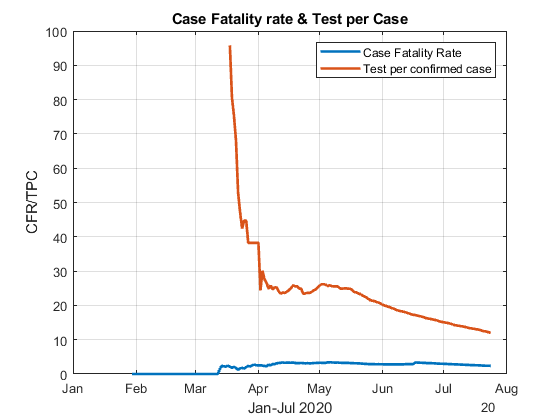

plot(x4.Date,x4.CaseFatalityRate___,"LineWidth",2)
hold on
plot(x4.Date,x4.TestsPerConfirmedCase,"LineWidth",2)
hold off
grid on
title("Case Fatality rate & Test per Case")
legend("Case Fatality Rate","Test per confirmed case")
xlabel("Jan-Jul 2020")
ylabel("CFR/TPC")

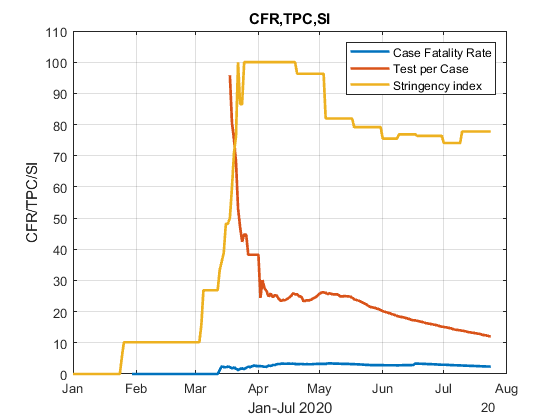

plot(x4.Date,x4.CaseFatalityRate___,"LineWidth",2)
hold on
plot(x4.Date,x4.TestsPerConfirmedCase,"LineWidth",2)
plot(x3.Date,x3.Stringency_Index,"LineWidth",2)
ylim([0.0 110.0])
legend("Case Fatality Rate","Test per Case", "Stringency index")
grid on
xlabel("Jan-Jul 2020")
ylabel("CFR/TPC/SI")
title("CFR,TPC,SI")
hold off

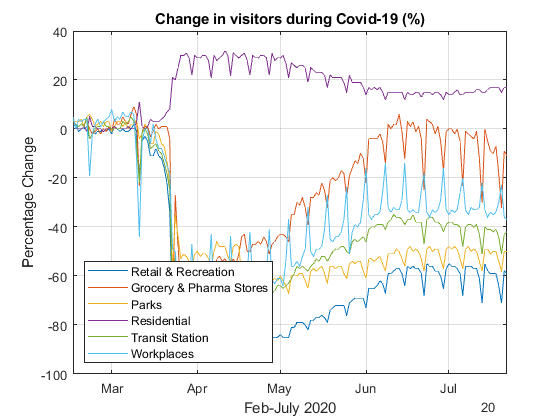

plot(x5.Date,x5.Retail_Recreation___)
hold on
plot(x5.Date,x5.Grocery_PharmacyStores___)
plot(x5.Date,x5.Parks___)
plot(x5.Date,x5.Residential___)
plot(x5.Date,x5.TransitStations___)
plot(x5.Date,x5.Workplaces___)
y=0
plot(y)
legend("Retail & Recreation","Grocery & Pharma Stores","Parks","Residential","Transit Station","Workplaces","Location","southwest")
xlim([datetime(20,2,16,0,0,0)...
      datetime(20,7,22,0,0,0)])
title("Change in visitors during Covid-19 (%)")
xlabel("Feb-July 2020")
ylabel("Percentage Change")
grid on
hold off